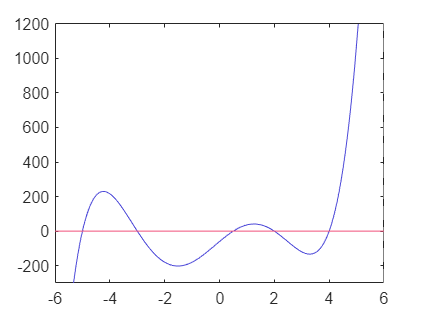

clc;
clear all;
close all;

syms x;
y1 = (x+5)*(x-4)*(x+3)*(x-2)*(x-1/2);%第一个非线性方程
y2 = (x+5)*(x-4)^2*(x+3)*(x+5/2);%第二个非线性方程
fplot(y1,'Color',[76, 72, 217]./256);
xlim([-6,6]);
ylim([-300,1200]);
hold on
line([-6,6],[0,0],'Color',[242, 80, 123]./256);%将画出（-6,0）到(6,0)的一条直线
hold off

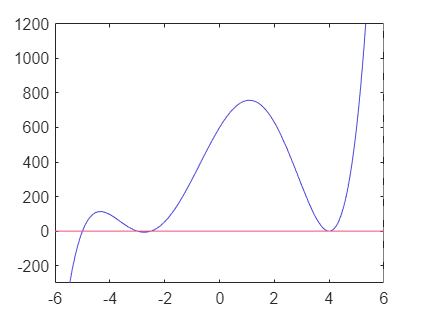

fplot(y2,'Color',[76, 72, 217]./256);
xlim([-6,6]);
ylim([-300,1200]);
hold on
line([-6,6],[0,0],'Color',[242, 80, 123]./256);%将画出（-6,0）到(6,0)的一条直线

%先初步判断零点的分布
%发现有四个零点，我们不妨将整个区间[-6,6]平分成4
x0 = zeros(1,5);
y1 = @f_1; 
y2 = @f_2;
y = y2;

k = 0;
L = 1/2;
 for i = -6:L:6  
    if(y(i)*y(i+L)<=0)
        k = k + 1;
        x0(k) = f_Bis(y,i,i+L,0.001);
    end
 end
fprintf("零点的横坐标为:")

零点的横坐标为:

x0 = unique(x0);
B(y,x0)

文件: B.m 行: 11 列: 10
'=' 运算符的使用不正确。 '=' 用于为变量赋值，'==' 用于比较值的相等性。

% function y1 = f_1(x)
%     y1 = (x+5)*(x-4)*(x+3)*(x-2)*(x-1/2)
% end

% function y2 = f_2(x)
%     y2 = (x+5)*(x-4)^2*(x+3)*(x+5/2);
% end